clear
syms x(t) A E M omega b
%Son 59 pisos
npisos = 59

npisos = 59

n = 59

n = 59

ms = ones(1,npisos)*640500; %[m1, m2,m3]
ks = ones(1,npisos)*667000%6.67*10^5  ;

ks =       667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000      667000


desplazamientos_iniciales = ones(1,59)*0;
velocidad_inicial = 0.1;
Msim = zeros(npisos,npisos);
Ksim = zeros(npisos,npisos);

for i = 1:npisos
    for j =1:npisos
        if i==j
            Msim(i,j) =ms(i);
        end
    end
end

Ksim(1,1) = ks(1) +ks(2);
Ksim(1,2) = -ks(2);
for i = 2:npisos-1
    for j =1:npisos
        if i==j
            Ksim(i,j) = ks(i)+ks(i+1);
        elseif j == i-1 
            Ksim(i,j) = -ks(i);
        elseif j ==i+1
            Ksim(i,j) = -ks(i+1);
        end    
    end
end

Ksim(end,end-1) = -ks(end);
Ksim(end,end) = ks(end);
A_num = -inv(Msim)*Ksim

A_num =    -2.0827    1.0414         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0
    1.0414   -2.0827    1.0414         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0 


%chance en los otros dos también me falta el negativo
[eigenvectores,eigenvalor] = eig(A_num);
disp('A')

A


A_num;
disp('Eigenvector')

Eigenvector


eigenvectores;
disp('Eigenvalores')

Eigenvalores


diag(eigenvalor);
disp('Frecuencia Natural')

Frecuencia Natural


frecuencia_natural = sqrt(diag(-eigenvalor))

frecuencia_natural =     2.0402
    2.0381
    2.0346
    2.0296
    2.0232
    2.0154
    2.0062
    1.9956
    1.9836
    1.9702


disp('Pereiodos de Vibración')

Pereiodos de Vibración


periodos_vibracion = ones(1,length(frecuencia_natural));
for i = 1:length(frecuencia_natural)
    periodos_vibracion(i) = 2*pi/frecuencia_natural(i);
end
periodos_vibracion

periodos_vibracion =     3.0796    3.0828    3.0882    3.0958    3.1056    3.1176    3.1319    3.1485    3.1675    3.1890    3.2131    3.2398    3.2692    3.3015    3.3368    3.3752    3.4169    3.4622    3.5111    3.5639    3.6209    3.6824    3.7486    3.8200    3.8969    3.9799    4.0693    4.1658    4.2700    4.3828    4.5048    4.6372    4.7810    4.9376    5.1085    5.2954    5.5006    5.7264    5.9759    6.2526    6.5611    6.9066    7.2960    7.7375    8.2420    8.8235    9.5005   10.2976   11.2494   12.4046


%./frecuencia_natural
disp('Modos naturales de vibración')

Modos naturales de vibración


eigenvectores

eigenvectores =     0.0097   -0.0193   -0.0289    0.0384    0.0478   -0.0571   -0.0662    0.0752    0.0839   -0.0924   -0.1006    0.1085    0.1162   -0.1235   -0.1305    0.1371    0.1433   -0.1492   -0.1546    0.1596    0.1641   -0.1682   -0.1718    0.1750    0.1776   -0.1798   -0.1814    0.1826    0.1832   -0.1833   -0.1829    0.1820    0.1806   -0.1787   -0.1763    0.1734    0.1701   -0.1662   -0.1619    0.1571    0.1519   -0.1463   -0.1403    0.1338    0.1270   -0.1199   -0.1124    0.1046    0.0965   -0.0882
   -0.0193    0.0384    0.0571   -0.0752   -0.0924    0.1085    0.1235   -0.1371   -0.1492    0.1596    0.1682   -0.1750   -0.1798    0.1826    0.1833   -0.1820   -0.1787    0.1734    0.1662   -0.1571   -0.1463    0.1338    0.1199   -0.1046   -0.0882    0.0707    0.0525   -0.0337   -0.0145   -0.0048   -0.0241    0.0432    0.0617   -0.0795   -0.0965    0.1124    0.1270   -0.1403   -0.1519    0.1619    0.1701   -0.1763   -0.1806    0.1829    0.1832   -0.1814   -0.1776    0.1718   

disp('Amplitudes de oscilación periodica')

Amplitudes de oscilación periodica


E_num = sqrt(desplazamientos_iniciales(1) + (velocidad_inicial./frecuencia_natural).^2 )

E_num =     0.0490
    0.0491
    0.0492
    0.0493
    0.0494
    0.0496
    0.0498
    0.0501
    0.0504
    0.0508


t_num = 0:0.1:5;

disp('Resolución Equación Diferencial.')

Resolución Equación Diferencial.


% Resolver la ecuación diferencial
disp('Ecuación')

Ecuación


eqn = A*x + E*omega^2*cos(omega*t)*b == diff(x, t, 2)

$$eqn(t) = A\,x\left(t\right)+\text{E}\,b\,\omega^{2}\,\cos\left(\omega \,t\right)=\frac{\partial^{2}}{\partial t^{2}}x\left(t\right)$$

sol = dsolve(eqn);
% Mostrar la solución
disp('Solución')

Solución


disp(sol)

$$\begin{array}{l} C_{1}\,{\mathrm{e}}^{\sqrt{A}\,t}+C_{2}\,{\mathrm{e}}^{-\sqrt{A}\,t}-\frac{\text{E}\,b\,\omega^{2}\,\left(\omega \,\sin\left(\omega \,t\right)+\sigma_{2}\right)}{\sigma_{1}}+\frac{\text{E}\,b\,\omega^{2}\,\left(\omega \,\sin\left(\omega \,t\right)-\sigma_{2}\right)}{\sigma_{1}}\\ \mathrm{where}\\ \sigma_{1}=2\,\sqrt{A}\,\left(\omega^{2}+A\right)\\ \sigma_{2}=\sqrt{A}\,\cos\left(\omega \,t\right) \end{array}$$

disp('Solución')

Solución


dx = diff(x,t)

$$dx(t) = \frac{\partial }{\partial t}x\left(t\right)$$

dA = diag(A_num);


sol_num = dsolve(eqn,[x(0) == 0, dx(0) == 0])

$$sol\_num = \frac{\text{E}\,b\,\omega^{2}\,{\mathrm{e}}^{-\sqrt{A}\,t}\,\left({\mathrm{e}}^{2\,\sqrt{A}\,t}-2\,{\mathrm{e}}^{\sqrt{A}\,t}\,\cos\left(\omega \,t\right)+1\right)}{2\,\left(\omega^{2}+A\right)}$$

sol0 = matlabFunction(sol_num)

sol0 = function_handle with value:
    @(A,E,b,omega,t)(E.*b.*omega.^2.*exp(-sqrt(A).*t).*(exp(sqrt(A).*t.*2.0)-exp(sqrt(A).*t).*cos(omega.*t).*2.0+1.0))./(A.*2.0+omega.^2.*2.0)


tarange = 0:0.05:5;
mat_desplazamiento0 = ones(length(tarange),npisos);
disp('Aux')

Aux


num = 1

num = 1

for t_aux = tarange
    mat_desplazamiento0(num,:) = diag(sol0(A_num,0.062,ones(n,1),diag(frecuencia_natural),t_aux));
    num = num+1;
end


mat_desplazamiento = ones(length(tarange),npisos);
num = 1

num = 1

for t_aux = tarange
    sigma = expm(-t_aux*(A_num)^1/2) * E_num.*frecuencia_natural.^2 ;
    sigma2 = expm(2*t_aux*(A_num)^1/2) ;
    sigma3 = -2*expm(t_aux*(A_num)^1/2) * cos(frecuencia_natural*t_aux) +1;
    lamda = 2*(frecuencia_natural.^2 + A_num);
    desplazamiento = inv(lamda)*(sigma2-sigma3)*sigma;
    mat_desplazamiento(num,:) = desplazamiento;
    num = num+1;
end


pisos_para_graficar = [1, 10, 20, 30, 40, 50,59];
figure;
hold on;
for i = 1:length(pisos_para_graficar)-1
    plot(tarange,mat_desplazamiento0(:, pisos_para_graficar(i)), 'DisplayName', ['Piso ', num2str(pisos_para_graficar(i))]);
end

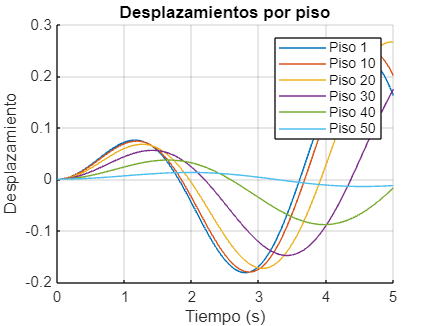

hold off;
xlabel('Tiempo (s)');
ylabel('Desplazamiento');
title('Desplazamientos por piso');
legend show;
grid on;

%{
tiempos = [1, 25,50,75,100];
figure;
hold on;
for i = 1:length(tiempos)
    plot(mat_desplazamiento0(tiempos(i),:), 'DisplayName', ['Tiempo: ', num2str(tarange(tiempos(i)))]);
end
hold off;
xlabel('Piso');
ylabel('Desplazamiento');
title('Desplazamientos del edificio');
legend show;
grid on;
%}

sol_num2 = dsolve(eqn,[x(0) == 0, dx(0) == 0.1])

$$sol\_num2 = \begin{array}{l} \frac{{\mathrm{e}}^{-\sqrt{A}\,t}\,\left(\omega^{2}\,\sigma_{1}-A+A\,\sigma_{1}-\omega^{2}+10\,\sqrt{A}\,\text{E}\,b\,\omega^{2}+10\,\sqrt{A}\,\text{E}\,b\,\omega^{2}\,\sigma_{1}-20\,\sqrt{A}\,\text{E}\,b\,\omega^{2}\,{\mathrm{e}}^{\sqrt{A}\,t}\,\cos\left(\omega \,t\right)\right)}{20\,\sqrt{A}\,\left(\omega^{2}+A\right)}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{2\,\sqrt{A}\,t} \end{array}$$

sol2 = matlabFunction(sol_num2)

sol2 = function_handle with value:
    @(A,E,b,omega,t)(1.0./sqrt(A).*exp(-sqrt(A).*t).*(-A+omega.^2.*exp(sqrt(A).*t.*2.0)+A.*exp(sqrt(A).*t.*2.0)-omega.^2+sqrt(A).*E.*b.*omega.^2.*1.0e+1+sqrt(A).*E.*b.*omega.^2.*exp(sqrt(A).*t.*2.0).*1.0e+1-sqrt(A).*E.*b.*omega.^2.*exp(sqrt(A).*t).*cos(omega.*t).*2.0e+1))./(A.*2.0e+1+omega.^2.*2.0e+1)


disp(matlabFunction(sol_num))

    @(A,E,b,omega,t)(E.*b.*omega.^2.*exp(-sqrt(A).*t).*(exp(sqrt(A).*t.*2.0)-exp(sqrt(A).*t).*cos(omega.*t).*2.0+1.0))./(A.*2.0+omega.^2.*2.0)




mat_desplazamiento = ones(length(tarange),npisos);
num = 1

num = 1


mat_desplazamiento2 = ones(length(tarange),npisos);
num = 1

num = 1

for t_aux = tarange
    mat_desplazamiento2(num,:) = diag(sol2(A_num,diag(E_num),ones(n,1),diag(frecuencia_natural),t_aux));
    num = num+1;
end


pisos_para_graficar = [1, 10, 20, 30, 40, 50,59];
figure;
hold on;
for i = 1:length(pisos_para_graficar)-1
    plot(tarange,mat_desplazamiento2(:, pisos_para_graficar(i)), 'DisplayName', ['Piso ', num2str(pisos_para_graficar(i))]);
end

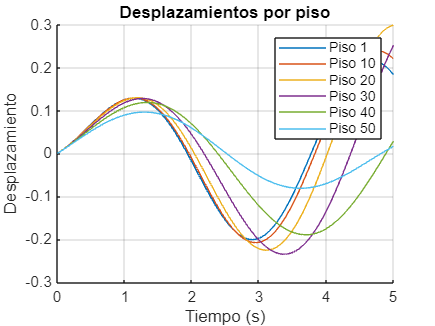

hold off;
xlabel('Tiempo (s)');
ylabel('Desplazamiento');
title('Desplazamientos por piso');
legend show;
grid on;